%ATTEMPTS
%1.Using additional control points
%2.Taking additional points along original curve as control points
%3.Linearly compacting the replanner time domain
%4.Warping the replanner time domain by an inverse normal distribution
%(incocnlusive)
%5.Skipping forward in the replanner time by the additional period added to
%tmax
%FIXED issue with knots and errors from replanner
%Small gap between two positional splines is due to the fact they are
%plotted separately, as the paths should not and do not overlap

%INCLUDE THESE GRAPHS - PARTICULARLY THE ONE WITH THE ORIGINAL AND
%REPLANNED

%MAKE THICKER TRENDS
%'CONSERVING DERIVATIVES OF MOTION CONTINUITY AND SMOOTHNESS

VMagMAT = absBS(VelMAT);
AMagMAT = absBS(AccMAT);
JMagMAT = absBS(JerkMAT);
SMagMAT = absBS(SnapMAT);
cVMagMAT = absBS(cVelMAT);
cAMagMAT = absBS(cAccMAT);
cJMagMAT = absBS(cJerkMAT);
cSMagMAT = absBS(cSnapMAT);

len = height(PosMAT);
intrpt = round(PFact*len);

tlin = linspace(0, intrpt, intrpt).';
tlin2 = linspace(intrpt+1, height(cPosMAT)+intrpt+1, height(cPosMAT)).';
pause = intrpt*pstep;

VCombMAT = [VMagMAT(1:intrpt,1)*pstep, VMagMAT(1:intrpt,2); cVMagMAT(:,1)*pstep+intrpt*pstep, cVMagMAT(:,2)];
ACombMAT = [tlin, AMagMAT(1:intrpt,2); tlin2, cAMagMAT(:,2)];
JCombMAT = [tlin, JMagMAT(1:intrpt,2); tlin2, cJMagMAT(:,2)];
SCombMAT = [tlin, SMagMAT(1:intrpt,2); tlin2, cSMagMAT(:,2)];

PosMAT(intrpt,:)

ans =    54.0732   37.4663


cPosMAT(1,:)

ans =    54.1271   37.6550


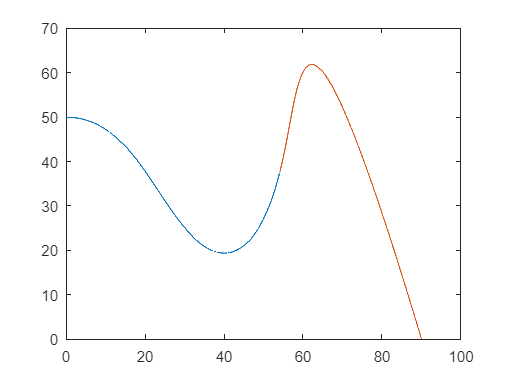


plot(PosMAT(1:intrpt,1),PosMAT(1:intrpt,2))
hold on
plot(cPosMAT(:,1),cPosMAT(:,2))
hold off

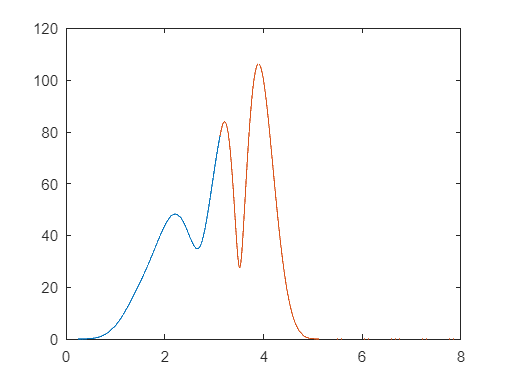

plot(VCombMAT(1:intrpt,1),VCombMAT(1:intrpt,2))
hold on
plot(VCombMAT(intrpt:end,1),VCombMAT(intrpt:end,2))
%hold off

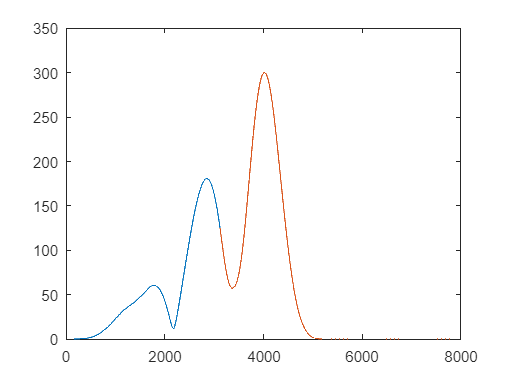

plot(ACombMAT(1:intrpt,1),ACombMAT(1:intrpt,2))
%hold on
plot(ACombMAT(intrpt:end,1),ACombMAT(intrpt:end,2))
hold off

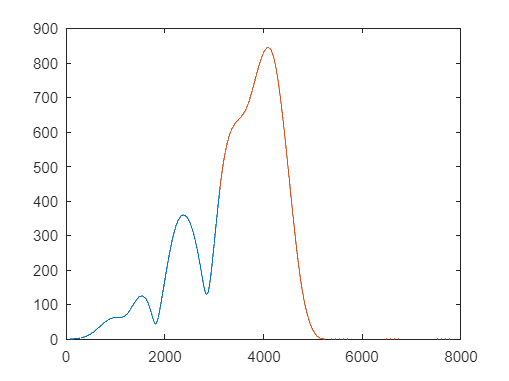

plot(JCombMAT(1:intrpt,1),JCombMAT(1:intrpt,2))
hold on
plot(JCombMAT(intrpt:end,1),JCombMAT(intrpt:end,2))
hold off

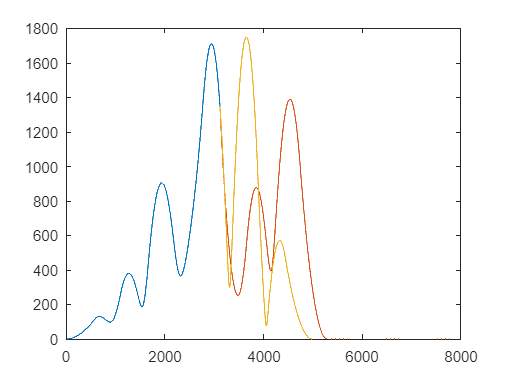

plot(SCombMAT(1:intrpt,1),SCombMAT(1:intrpt,2))
hold on
plot(SCombMAT(intrpt:end,1),SCombMAT(intrpt:end,2))
plot(SMagMAT(intrpt:end,1),SMagMAT(intrpt:end,2))
hold off


c = 1;
ht = height(PosMAT);
ComFact = height(cPosMAT)/height(PosMAT(intrpt:end,:))

ComFact = 2.6015

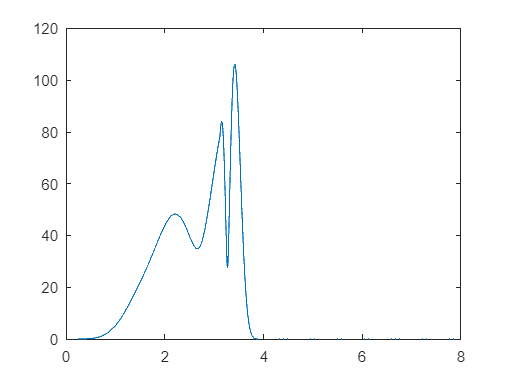

for i = intrpt:1:ht
    row = floor(ComFact*c);
    VCombMAT(i,2) = cVMagMAT(row, 2);
    ACombMAT(i,2) = cAMagMAT(row, 2);
    JCombMAT(i,2) = cJMagMAT(row, 2);
    SCombMAT(i,2) = cSMagMAT(row, 2);
    c = c+1;
end
for i = (intrpt+c-1):1:height(VCombMAT)
    VCombMAT(i,2) = 0;
    ACombMAT(i,2) = 0;
    JCombMAT(i,2) = 0;
    SCombMAT(i,2) = 0;
end
plot(VCombMAT(:,1), VCombMAT(:,2))

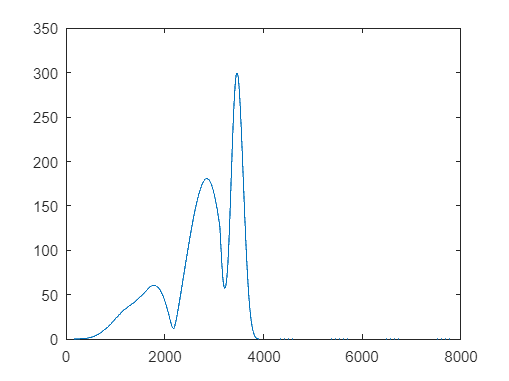

plot(ACombMAT(:,1), ACombMAT(:,2))

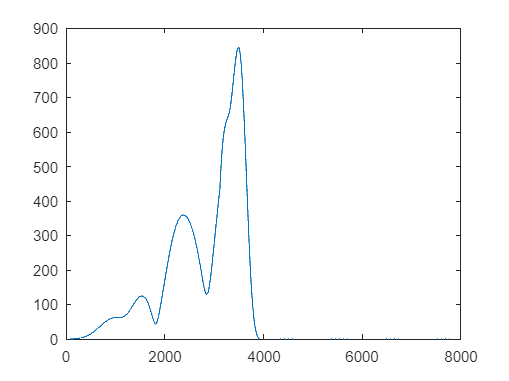

plot(JCombMAT(:,1), JCombMAT(:,2))

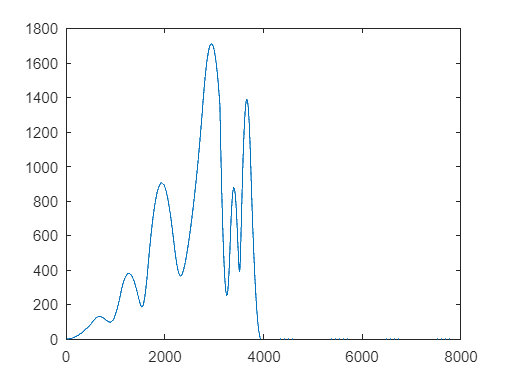

plot(SCombMAT(:,1), SCombMAT(:,2))

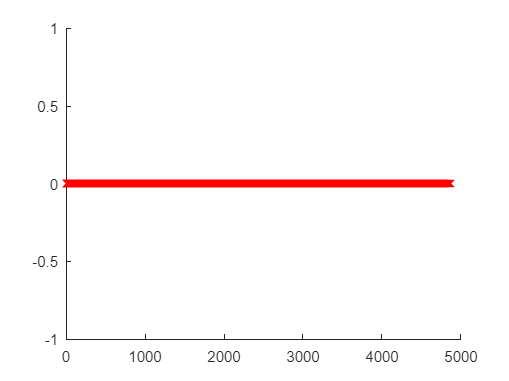


x = cVMagMAT(:,1);
y = zeros(height(x),1);
scatter(x, y, 50, 'X', 'red')

max = x(end)/2;
x2 = [];
for i = 1:1:height(x)
    Q = ((1/max)*x(i)-1)^2;
    if x(i) > max
        x2(i,1) = x(i) + Q*(max*2-x(i));
    else
        x2(i,1) = x(i) - Q*x(i);
    end
end
x

x =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


x2

x2 = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001


scatter(x2, y, 50, 'X', 'red')

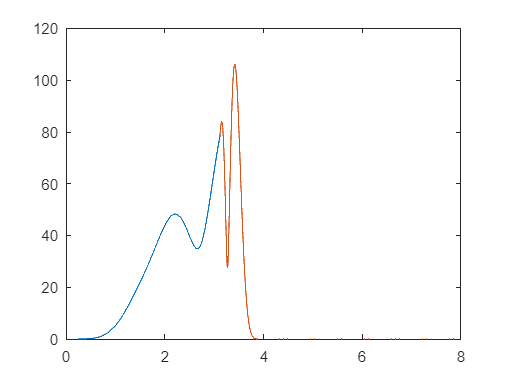

cVMagMAT(:,1) = x2(:);
plot(VCombMAT(1:intrpt,1),VCombMAT(1:intrpt,2))
hold on
plot(VCombMAT(intrpt:end,1),VCombMAT(intrpt:end,2))
hold off

function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end